# VSPAero Coefficient Parser

This code is intended to guide the user through the transition from OpenVSP to a Simulink plant model consisting of lookup tables generated from VSPAero analysis results. 

## Theory

 For simulation, a set of coefficients will be created and stored in 2D tables. According to reference [1], the important coefficients are as follows.

Drag: $C_D = C_D(\alpha, \beta, M, h) + \Delta C_D (M, \delta_e) + \Delta C_D (M, \delta_r) + \Delta C_D (M, \delta_F)$

Lift: $C_L = C_L(\alpha, \beta, M, T_c) + \Delta C_L (M, \delta_F) + \Delta C_{L _{ge}}(h)$

Side Force: $C_Y = C_Y(\alpha, \beta, M) + \Delta C_{Y_{\delta r}} (\alpha, \beta, M, \delta_r) + \Delta C_{Y_{\delta a}} (\alpha, \beta, M, \delta_a) + \frac {b} {2 V_T} [ C_{Y_p}(\alpha, M)P+C_{Y_r}(\alpha, M)R]$

Rolling Moment: $C_l = C_l(\alpha, \beta, M) + \Delta C_{l_{\delta r}} (\alpha, \beta, M, \delta_r) + \Delta C_{l_{\delta a}} (\alpha, \beta, M, \delta_a) + \frac {b} {2 V_T} [ C_{l_p}(\alpha, M)P+C_{l_r}(\alpha, M)R]$

Pitching Moment: $C_m = C_m(\alpha, M, h, \delta_f, T_c) + \Delta C_{m_{\delta e}} (\alpha, M, h, \delta_e) + \Delta C_{m_{thrust}} (\delta_t, M, h) + \frac {mac} {2 V_T} [ C_{m_q}Q+C_{m_\dot a}\dot \alpha]$   (some coefficients handled by Simulink omitted)

Yawing Moment: $C_n = C_n(\alpha, \beta, M, T_c) + \Delta C_{n_{\delta r}} (\alpha, \beta, M, \delta_r) + \Delta C_{n_{\delta a}} (\alpha, \beta, M, \delta_a) + \frac {b} {2 V_T} [ C_{n_p}(\alpha, M)P+C_{n_r}(\alpha, M)R]$

In Simulink, the coordinate system reference is the same as in reference [1]. Since OpenVSP does not have this same reference frame, some coefficient values must be changed to accommodate the proper directions.

## Step 1: Create Model & Reference Values

First, create your model in Open VSP. Using your main reference wing, enter the values of Span, Chord, and Area into the boxes below. 

Note: generally the planform area, mean aerodynamic chord, and full span length of the main wing are used. However, these values can be user specified as long as they are then used consistently for all future calculations.

Note 2: Make sure to keep track of your units. Open VSP will follow the user specified units.

Aero.Sref = 378; % Planform Area
Aero.bref = 48; % Wingspan
Aero.Cref = 7.875; % Reference chord
Aero.units = "Inches";

### Aerodynamic Moment Reference Position

While the moment reference position can be chosen as any location, generally the quarter chord location of the wing is used [1]. First, calculate the quarter chord location using the OpenVSP axis definitions. This coordinate must be entered into the VSPAero Moment Reference Position as seen below.

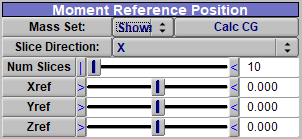

 For all further analysis, this point will be considered the aerodynamic center (AC), the center of pressure (CP), or the neutral point (NP). Provide the AC below in the form $[x, y, z]$

Aero.Mref = [10.72 0 -2.5]; % Moment reference position

## Step 2: Generate Static Coefficients

In this step the following coefficients are obtained: $C_L, C_D, C_Y, C_l, C_m, C_n$ 

First, run VSPAero to create static stability coefficients. This is done by running an alpha/beta sweep with Stability Type set to "off." Once the model is run, look for a .polar file from VSPAero outputs. After running VSPAero, the result files will be stored in the location of the model file. Find the .polar file and load it into the variable below.

data_path = "C:\Users\Tristan\Program Files\OpenVSP-3.41.2-win64-Python3.11\OpenVSP-3.41.2-win64\Models\T28 Static Analysis\T28_Trojan_DegenGeom.polar";
polar_data = readtable(data_path, 'FileType','text')

polar_data = 165×23 table
    Beta    Mach    AoA    Re_1e6       CL           CDo          CDi        CDtot         CDt       CDtot_t        CS         L_D          E           CFx          CFy          CFz          CMx          CMy         CMz         CMl          CMm          CMn       FOpt
    ____    ____    ___    ______    _________    _________    _________    ________    _________    ________    ________    <s

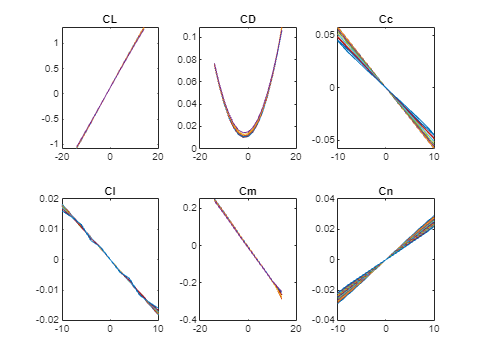

Aero.beta_vec= unique(polar_data.Beta)';
Aero.alpha_vec= unique(polar_data.AoA)';
N_alpha = length(Aero.alpha_vec);
N_beta = length(Aero.beta_vec);

% Store coefficients in wind axes
% Wind axes are defined in the aero coefficients simulink block
Aero.CL = reshape(table2array(polar_data(:,"CL")), [N_alpha, N_beta])';
Aero.CD = reshape(table2array(polar_data(:,"CDtot")), [N_alpha, N_beta])';
Aero.Cc = reshape(table2array(polar_data(:,"CS")), [N_alpha, N_beta])';
Aero.Cl = reshape(table2array(polar_data(:,"CMl")), [N_alpha, N_beta])';
Aero.Cm = reshape(table2array(polar_data(:,"CMm")), [N_alpha, N_beta])';
Aero.Cn = reshape(table2array(polar_data(:,"CMn")), [N_alpha, N_beta])';

%Plot data
tiledlayout(2,3)
nexttile
plot(Aero.alpha_vec, Aero.CL)
title("CL")
nexttile
plot(Aero.alpha_vec, Aero.CD)
title("CD")
nexttile
plot(Aero.beta_vec, Aero.Cc)
title("Cc")
nexttile
plot(Aero.beta_vec, Aero.Cl)
title("Cl")
nexttile
plot(Aero.alpha_vec, Aero.Cm)
title("Cm")
nexttile
plot(Aero.beta_vec, Aero.Cn)
title("Cn")

## Step 3: Obtain Rate Coefficients

In this step we will obtain the following coefficients: $C_{Y_p}, C_{Y_r}, C_{l_p}, C_{l_r}, C_{m_q}, C_{n_p}, C_{n_r}$along with the coefficients for the control surfaces.

Cmq can be obtained from a q analysis which will also add the alpha dot term.

To do this you must run a VSPAero analysis with the Run mode set to "Steady." This analysis will use the alpha/beta/mach/velocity points as bases then perturb the simulation by 1 unit. The difference between the two analyses for each point will be divided by the unit of change to create rate coefficients.

In addition to pitch/roll/yaw rate coefficients, the perturbations can include control surface deflections. To include these deflection you must create control surface groupings in the Control Grouping tab.

Once your analysis has been complete a .stab file will be generated with the analysis results. Find this file and load it below. The following function will parse the values.

stab_dir= "C:\Users\Tristan\Program Files\OpenVSP-3.41.2-win64-Python3.11\OpenVSP-3.41.2-win64\Models\T28 Stab with ctrl surf\goodRun1.stab";
stab_data = parseVSPAero_stab(stab_dir);

### Angular Rate Coefficients (Convert to Simulink 6DOF Wind-Axes)

To create lookup tables for Simulink, the following variables are used.

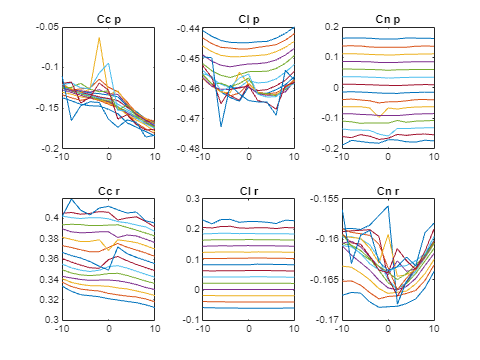

Aero.Cc_p = stab_data.CS_p;
Aero.Cc_r = stab_data.CS_r;
Aero.Cl_p = stab_data.CMl_p;
Aero.Cl_r = stab_data.CMl_r;
Aero.Cm_q = stab_data.CMm_q;
Aero.Cn_p = stab_data.CMn_p;
Aero.Cn_r = stab_data.CMn_r;

%Plot data
tiledlayout(2,3)
nexttile
plot(Aero.beta_vec, Aero.Cc_p)
title("Cc p")
nexttile
plot(Aero.beta_vec, Aero.Cl_p)
title("Cl p")
nexttile
plot(Aero.beta_vec, Aero.Cn_p)
title("Cn p")
nexttile
plot(Aero.beta_vec, Aero.Cc_r)
title("Cc r")
nexttile
plot(Aero.beta_vec, Aero.Cl_r)
title("Cl r")
nexttile
plot(Aero.beta_vec, Aero.Cn_r)
title("Cn r")

### Control Surface Deflection Coefficients

Necessary drag coefficient deltas (per degree) $C_{D_{\delta e}}, C_{D_{\delta r}}, C_{D_{\delta F}}$

Necessary side force coefficient deltas (per degree) $C_{Y_{\delta r}}, C_{Y_{\delta a}}$

Necessary lift coefficient deltas (per degree) $C_{L_{\delta F}}$

Necessary rolling moment coefficient deltas (per degree) $C_{l_{\delta r}}, C_{l_{\delta a}}$

Necessary pitching moment coefficient deltas (per degree) $C_{m_{\delta e}}$

Necessary yawing moment coefficient deltas (per degree) $C_{n_{\delta r}}, C_{n_{\delta a}}$

Use the boxes below to indicate which control surface corresponds to which OpenVSP control surface grouping.

aileron = 1;
elevator=3;
flap = 2;
rudder = 4;

% Drag coefficients
Aero.CD_de = stab_data.CD_ds(:,:,elevator);
Aero.CD_dr = stab_data.CD_ds(:,:,rudder);
Aero.CD_dF = stab_data.CD_ds(:,:,flap);

% Lift coefficient
Aero.CL_dF = stab_data.CL_ds(:,:,flap);

% Side force coefficient
Aero.Cc_dr = stab_data.CS_ds(:,:,rudder);
Aero.Cc_da = stab_data.CS_ds(:,:,aileron);

% Rolling moment coefficient
Aero.Cl_dr = stab_data.CMl_ds(:,:,rudder);
Aero.Cl_da = stab_data.CMl_ds(:,:,aileron);

% Pitching moment coefficient
Aero.Cm_de = stab_data.CMm_ds(:,:,elevator);

% Yawing moment coefficient
Aero.Cn_dr = stab_data.CMn_ds(:,:,rudder);
Aero.Cn_da = stab_data.CMn_ds(:,:,aileron);

## Step 4: Mass/MOI Values

Use OpenVSP or other analysis to determine the CG, mass and inertia

AC.CG = [10.5, 0, 0];
AC.mass = 0.115; % slugs
AC.Inertia = diag([11.38 9.6 20.40]); %slug-in^2



mot.Kv = 300;
mot.amp = 100;

## OpenVSP Notes

OpenVSP Note:The coefficient $C_{\delta e}$ should result in a positive pitching moment. In the 6-DOF simulink block the Y axis points out the right wing meaning a positive moment would come from an upwards deflection of the elevator control surface. In OpenVSP, control surface directions are naturally down for the right wing and up for the left wing.

## References

[1] Stevens, B. L., and F. L. Lewis, *Aircraft Control and Simulation,* John Wiley & Sons, New York, 1992